% Par set 1
%{
Lambda = 0.0004;
mu = Lambda;
b = Lambda;
beta = 2.5;
gamma = 1;
epsilon = 1;
alpha_i = 0;
alpha_s = 0.0008;
%}

% Par set 2

Lambda = 0.0004;
mu = Lambda;
b = Lambda;
beta = 1.5;
gamma = 1;
epsilon = 0.5;
alpha_i = 0;
alpha_s = 0.0001;


chadi_par_keys = ["Lambda" "mu" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];
shrader_par_keys = ["b" "beta" "gamma" "epsilon" "alpha_i" "alpha_s"];

chadi_par_values = [Lambda mu beta gamma epsilon alpha_i alpha_s];
shrader_par_values = [b beta gamma epsilon alpha_i alpha_s];

chadi_par_dictionary = dictionary(chadi_par_keys, chadi_par_values);
shrader_par_dictionary = dictionary(shrader_par_keys, shrader_par_values);

tspan = [0 10000];
i0 = 1e-2;
x0_chadi = [1 - i0; i0; 0];
x0_shrader = [1 - i0; i0];

chadi_odefun = @(t,x) chadi_model(t, x, chadi_par_dictionary);
shrader_odefun = @(t,x) shrader_model(t, x, shrader_par_dictionary);
chadi_sol = ode89(chadi_odefun, tspan, x0_chadi)

chadi_sol = struct with fields:
     solver: 'ode89'
    extdata: [1×1 struct]
          x: [0 0.0371 0.2228 1.1511 5.7927 11.4605 16.4258 23.6380 33.5335 46.5789 58.1539 73.1236 88.7984 109.3237 133.7915 166.7932 207.7835 245.4760 276.1358 308.4098 352.2990 406.8759 458.4509 504.0150 556.8130 632.5243 734.9046 … ] (1×104 double)
          y: [3×104 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


shrader_sol = ode89(shrader_odefun, tspan, x0_shrader)

shrader_sol = struct with fields:
     solver: 'ode89'
    extdata: [1×1 struct]
          x: [0 0.7663 4.5975 10.2741 15.4162 22.1324 31.8969 44.4585 56.6159 70.8651 87.0576 107.0855 131.8896 164.8898 208.0827 252.4497 290.9588 330.8836 385.9078 461.5857 551.8482 669.4499 1.0310e+03 1.0920e+03 1.1123e+03 1.1326e+03 … ] (1×100 double)
          y: [2×100 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


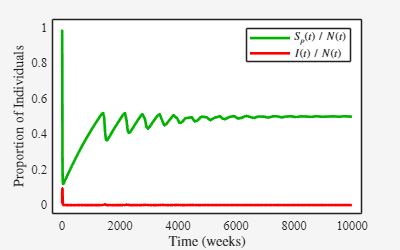

chadi_fig = figure("Position", [0 0 400 250]);
axis = axes(chadi_fig);
hold on;
N_time_series = sum(chadi_sol.y, 1);
plot(chadi_sol.x, chadi_sol.y(1,:) ./ N_time_series, "DisplayName", "$S_p(t)\; /\; N(t)$", "Color", [0 0.7 0], "LineWidth", 2);
plot(chadi_sol.x, chadi_sol.y(2,:) ./ N_time_series, "DisplayName", "$I(t)\; /\; N(t)$", "Color", [1 0 0], "LineWidth", 2);
xlabel("Time (weeks)", "Interpreter", "latex");
ylabel("Proportion of Individuals", "Interpreter", "latex")
legend("Interpreter", "latex");
box(axis, "on");
axis.XAxis.TickLength = [0 0];
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.TickLength = [0 0];
axis.YAxis.FontName = "Times New Roman";

% Add axis padding
xlen = chadi_sol.x(end);
x_pad = xlen*0.035;
xlim([-x_pad, xlen + x_pad]);
ylim([-0.05, 1.05]);

theme(chadi_fig, "light");
hold off;

exportgraphics(chadi_fig, "MA_time_series_par_set_2.png", "Resolution", 300);

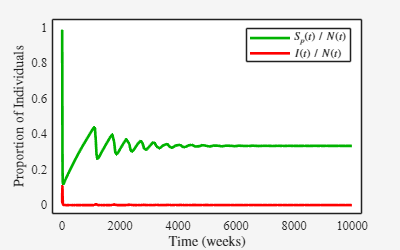


shrader_fig = figure("Position", [0 0 400 250]);
axis = axes(shrader_fig);
hold on;
plot(shrader_sol.x, shrader_sol.y(1,:), "DisplayName", "$S_p(t)\; /\; N(t)$", "Color", [0 0.7 0], "LineWidth", 2);
plot(shrader_sol.x, shrader_sol.y(2,:), "DisplayName", "$I(t)\; /\; N(t)$", "Color", [1 0 0], "LineWidth", 2);
xlabel("Time (weeks)", "Interpreter", "latex");
ylabel("Proportion of Individuals", "Interpreter", "latex")
legend("Interpreter", "latex");
box(axis, "on");
axis.XAxis.TickLength = [0 0];
axis.XAxis.FontName = "Times New Roman";
axis.YAxis.TickLength = [0 0];
axis.YAxis.FontName = "Times New Roman";

% Add axis padding
xlen = chadi_sol.x(end);
x_pad = xlen*0.035;
xlim([-x_pad, xlen + x_pad]);
ylim([-0.05, 1.05]);

theme(shrader_fig, "light");
hold off;

exportgraphics(shrader_fig, "ST_time_series_par_set_2.png", "Resolution", "300");

function dx_dt = chadi_model(t, x, par_dictionary)
    Lambda = par_dictionary("Lambda");
    mu = par_dictionary("mu");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    Sp = x(1);
    I = x(2);
    Ss = x(3);

    dSp_dt = Lambda - beta*Sp*I - mu*Sp;
    dI_dt = beta*Sp*I + epsilon*beta*Ss*I - (gamma + mu + alpha_i)*I;
    dSs_dt = gamma*I - epsilon*beta*Ss*I - (mu + alpha_s)*Ss;

    dx_dt = [dSp_dt; dI_dt; dSs_dt];
end

function dx_dt = shrader_model(t, x, par_dictionary)
    b = par_dictionary("b");
    beta = par_dictionary("beta");
    gamma = par_dictionary("gamma");
    epsilon = par_dictionary("epsilon");
    alpha_i = par_dictionary("alpha_i");
    alpha_s = par_dictionary("alpha_s");

    sp = x(1);
    i = x(2);
    ss = 1 - sp - i;

    dsp_dt = b - b*sp - beta*sp*i + alpha_i*sp*i + alpha_s*sp*ss;
    di_dt = beta*sp*i + epsilon*beta*i*ss - (b + gamma + alpha_i)*i + alpha_i*i*i + alpha_s*i*ss;

    dx_dt = [dsp_dt; di_dt];
end